IZO_st.name='IZO'; 
IZO_st.lat=28.309;
IZO_st.lon=-16.4994;
IZO_st.alt=2373;
IZO_st.env='Mt';
IZO_st.footp='Mx';


IZO_rd=read_betsy('izo_2006_2018',IZO_st.name);



datevec(IZO_rd.Time(1))

ans =         2006          11           2           0           0           0


datevec(IZO_rd.Time(end))

ans =         2019           1           1           0           0           0


prctile(IZO_rd.U_S11,[5 50 95])

ans =     5.5000   15.3500   33.4500


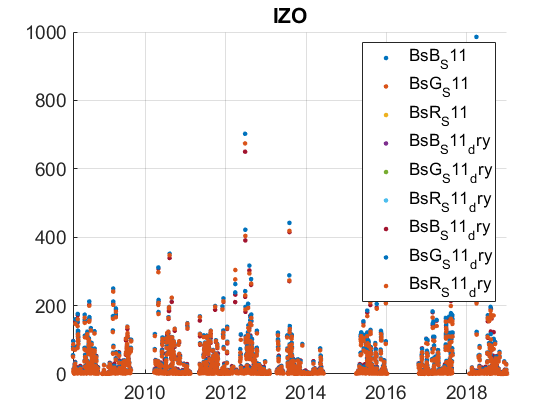

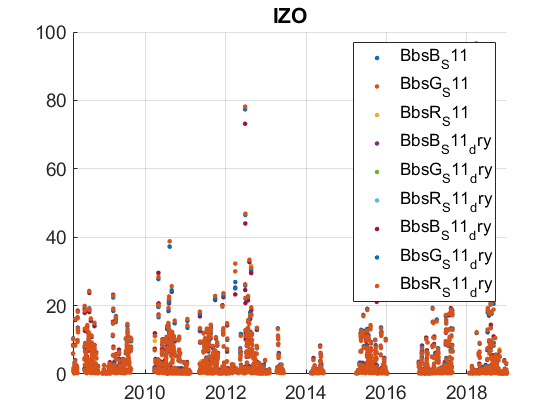

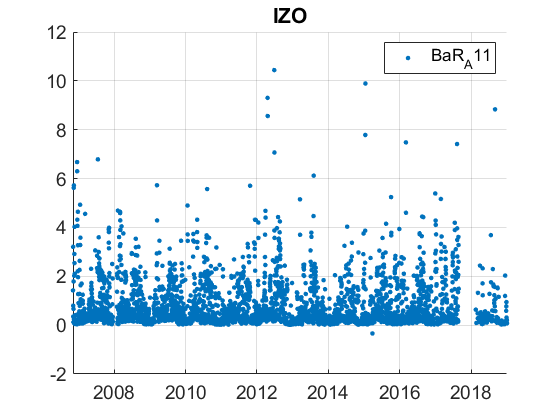

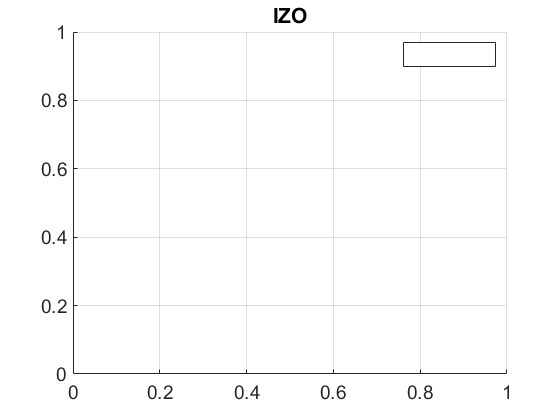

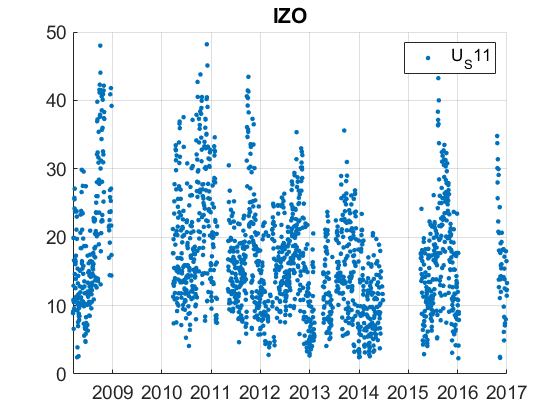

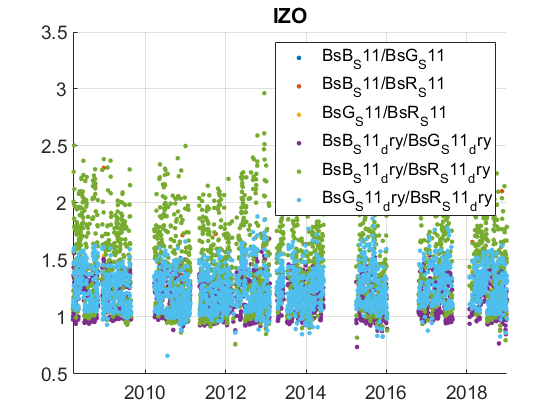

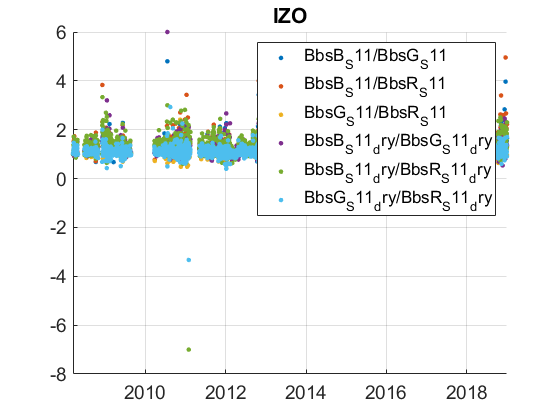

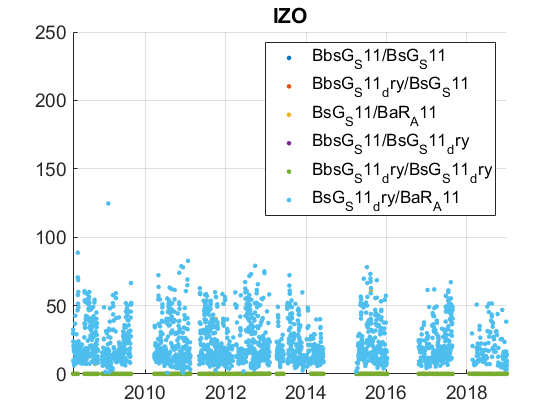

%  prctile(IZO_rd.U0_S,[5 50 95])
%  prctile(IZO_rd.U1_S,[5 50 95])
% prctile(IZO_rd.Uu1_S,[5 50 95])
plotFigControl(IZO_rd,IZO_st.name);

% 1 size cut, ok
% sc: ok, no negatives,no clear seasonal cycle
% figure
% plot(IZO_rd.Time,IZO_rd.U_S11,'.');

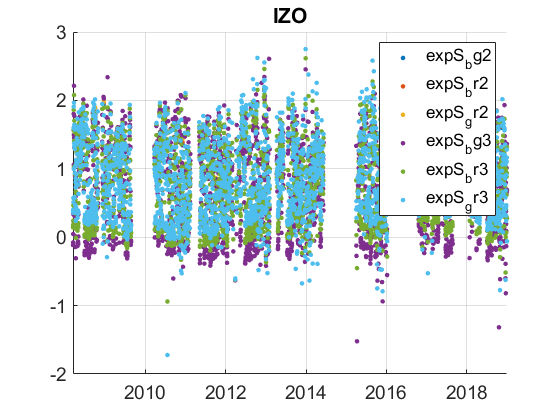

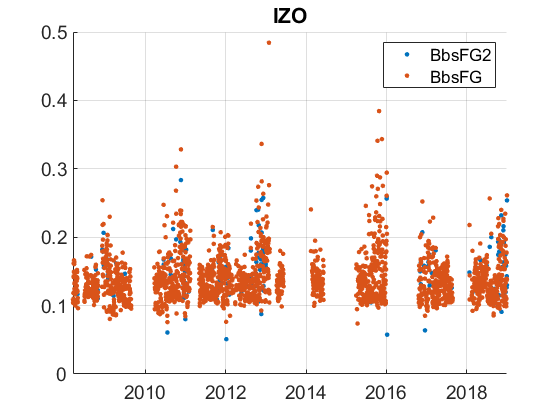

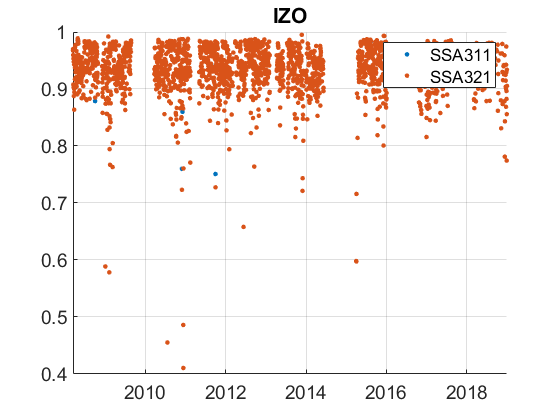

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
IZO_cal=compute_exp_SSA(IZO_rd,lambdaSC, lambdaAE);
plotFigControl_cal(IZO_cal, IZO_st.name);

%Questions:
%problems:

%RH: it seems that there is a decrease of Humidity, is there any change in the drying process ?

%scat: there is a lot of long holes: are they real or due to databank problems ?


IZO_tr=IZO_rd;
IZO_tr.y=year(IZO_tr.Time);
% begin at the beginning of a year: 2007 for abs, 2009 for scat
%end: 2017
P=timerange('2007-01-01','2019-01-01');
IZO_tr=IZO_tr(P,:);

%do not compute dry
names=fieldnames(IZO_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) |  contains(names,'_dry');
N=names(c);
for i=1:length(N)
    IZO_tr.(N{i})=[];
end
% begin at the beginning of a year:  2009 for scat
Ps=timerange('2007-01-01','2009-01-01');
names=fieldnames(IZO_tr);
c=startsWith(names,["Bs";"Bbs";"U"]);
N=names(c)

N = 7×1 cell array
    {'BsB_S11' }
    {'BsG_S11' }
    {'BsR_S11' }
    {'BbsB_S11'}
    {'BbsG_S11'}
    {'BbsR_S11'}
    {'U_S11'   }

for i=1:length(N)
    IZO_tr.(N{i})(Ps)=NaN;
end

%change in RH: compute RH trend


%nephelometer: difficult to compute trend ending in 2016 since the 3/4 of the year
%are missing

% abs change for green wavelenght to compute SSA
IZO_tr.BaR_A11=IZO_tr.BaR_A11.*(637/550)

IZO_tr = 4383×9 timetable
            Time            BsB_S11    BsG_S11    BsR_S11    BbsB_S11    BbsG_S11    BbsR_S11    BaR_A11     U_S11     y  
    ____________________    _______    _______    _______    ________    ________    ________    ________    _____    ____
    01-Jan-2007 00:00:00      NaN        NaN        NaN        NaN         NaN         NaN        0.53276     NaN     2007
    02-Jan-2007 00:00:00      NaN        NaN        NaN        NaN         NaN         NaN         1.0424     NaN     2007
    03-Jan-2007 00:00:00      NaN        NaN        NaN        NaN         NaN         NaN 

IZO_cal2=compute_exp_SSA(IZO_tr,lambdaSC, lambdaAE);
IZO_tr=outerjoin(IZO_tr, IZO_cal2);

%do not compute trend on B, R and exp with red
IZO_tr.BsB_S11=[];
IZO_tr.BsR_S11=[];
IZO_tr.BbsB_S11=[];
IZO_tr.BbsR_S11=[];

IZO_tr.expS_br3=[]

IZO_tr = 4383×9 timetable
            Time            BsG_S11    BbsG_S11    BaR_A11     U_S11     y      BbsFG    expS_bg3    expS_gr3    SSA311
    ____________________    _______    ________    ________    _____    ____    _____    ________    ________    ______
    01-Jan-2007 00:00:00      NaN        NaN        0.53276     NaN     2007     NaN       NaN         NaN        NaN  
    02-Jan-2007 00:00:00      NaN        NaN         1.0424     NaN     2007     NaN       NaN         NaN        NaN  
    03-Jan-2007 00:00:00      NaN        NaN        0.37641     NaN     2007     NaN       NaN         

IZO_tr.expS_gr3=[];

IZO_result= all_trend_STN(IZO_tr,IZO_st); 
plot_10y_in_two(IZO_result, IZO_st);

IZO_result_D=IZO_result;